## Alpha3 oscillators

The alpha3 uses two kinds of oscillators:

- 3 segment multi-shape oscillators (3S): used as the first oscillator of the DCO

- 5 segments multi-shape oscillators (5S): used as the second oscillator of the DCO and the LFOs

Those two kinds of oscillators allow to quickly create variations of the elementary signals (square, sawtooth and triangle), with intermediate results; thus the name "multi-shape".

### 3S oscillator

TODO

### 5S oscillator

The 5 segments oscillator can generate different kinds of signals and variations of those signals, using two parameters:

- **Pulse Width**: represents the position of the point with the maximum amplitude

- **Saturation**: amplifies the basic signal, which becomes saturated

The oscillator is denoted as "5 segments" because the combination of the pulse width and the saturation creates a shape composed of 5 segments:

- Segment 1: a straight line with the minimum amplitude

- Segment 2: a slope that grows from the minimum to the maximum amplitude

- Segment 3: a straight line at the maximum amplitude

- Segment 4: a slope that descends from the maximum amplitude to the minimum amplitude

- Segment 5: a straight line at the minimum amplitude

Notice that segment 1, 3 and 5 are non-null if and only if the signal is saturated.

#### 5S pulse width

Purpose of the pulse width is to create a basic shape that varies from an inverted sawtooth to a sawtooth with an intermediate state representing a triangle. Assuming that no saturation is appied:

- When the pulse width is null, the resulting signal is an inverted sawtooth

- When the pulse width is at half of the maximum width, the resulting signal is a triangle

- When the pulse width is at its maximum, the resulting signal is a sawtooth

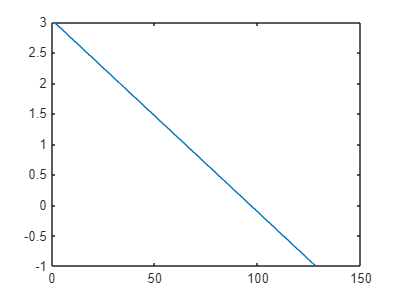

wave_len = 128;
pulse_width = wave_len / 2;
id = linspace(0, wave_len, wave_len);
plot(triangle(id, pulse_width, wave_len));

#### 5S saturation

TODO

function sample = triangle(id, pw, wave_len)
% The output is a signal in range [-1,1] which is then rescaled wrt
% saturation
min = -1;
max = 1;
amp = max - min;
if id < pw
    sample = single(min + amp * id / pw);
else
    slope = wave_len - pw;
    sample = single(max - amp * (id - pw) / slope);
end
end